% Set up a tcpclient to connect to the Python server
t = tcpclient('localhost', 65432);  % Host and port must match Python

disp('Connected to Python!');

Connected to Python!


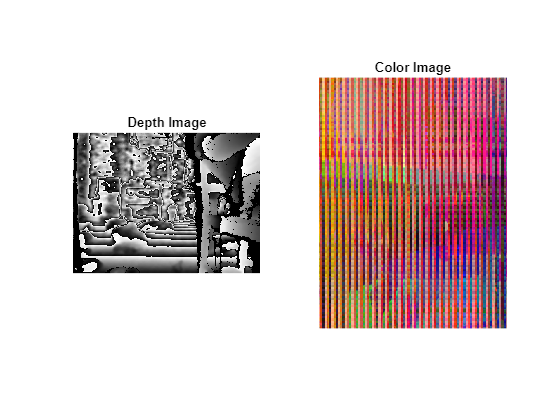


% Define the dimensions of the incoming images
depth_width = 640;
depth_height = 480;
color_width = 640;
color_height = 480;
color_channels = 3;

% Prepare to receive data
depth_data = uint16(zeros(depth_height, depth_width));
color_data = uint8(zeros(color_height, color_width, color_channels));

while true
    % Receive the depth data first
    depth_buffer = read(t, depth_width * depth_height * 2);  % 2 bytes per pixel for uint16
    if isempty(depth_buffer)
        break;
    end
    depth_image = typecast(depth_buffer, 'uint16');
    depth_image = reshape(depth_image, [depth_width, depth_height])';

    % Read until 'BREAK' is encountered (indicating color data is next)
    while true
        delimiter = char(read(t, 5));
        if strcmp(delimiter, 'BREAK')
            break;
        end
    end

    % Now receive the color data
    color_buffer = read(t, color_width * color_height * color_channels);  % RGB image
    if isempty(color_buffer)
        break;
    end
    color_image = typecast(color_buffer, 'uint8');
    color_image = reshape(color_image, [color_width, color_height, color_channels]);

    % Display the depth and color images
    figure(1);
    subplot(1, 2, 1), imshow(depth_image, []), title('Depth Image');
    subplot(1, 2, 2), imshow(color_image), title('Color Image');
    drawnow;

    % Read until 'END' is encountered, indicating the frame transmission is over
    while true
        delimiter = char(read(t, 3));
        if strcmp(delimiter, 'END')
            break;
        end
    end
end